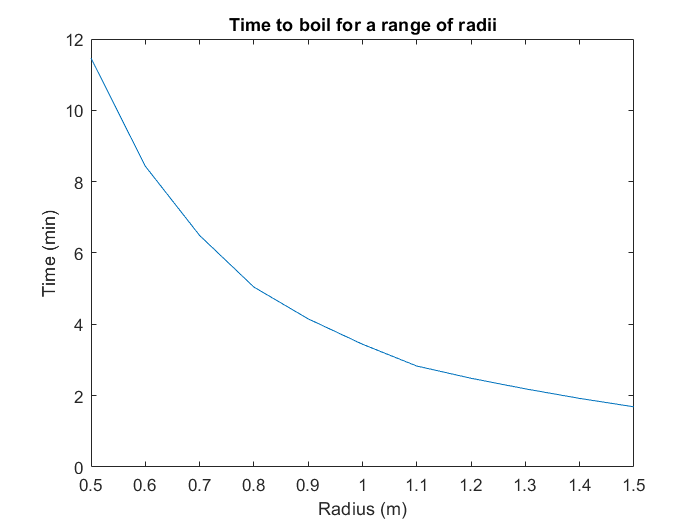

clear
sweep_range=0.5:0.1:1.5;
J = zeros(size(sweep_range, 2), 2);
for i=1:length(sweep_range)
    [T, M, boil_time] = solar_cooker_sim(sweep_range(i));
    J(i,:) = [sweep_range(i), boil_time];
end
plot(J(:,1), J(:,2))
xlabel("Radius (m)")
ylabel("Time (min)")
title("Time to boil for a range of radii")